Project 2 Neural Network Optimization

(a) Using the sigmoid function defined above, compute an expression for the gradient ∇w fw(x). You can leave the expression in terms of φ and the derivative of φ. ∗

**∇w fw(x) = [φ(w2x1+w3x2+w4x3+w5) **

** x1w1φ'(w2x1 + w3x2+w4x3+w5)**

**  x2w1φ'(w2x1+w3x2+w4x3+w5) **

** x3w1φ'(w2x1+w3x2+w4x3+w5) **

** w1φ'(w2x1+w3x2+w4x3+w5)**

**φ(w7x1 + w8x2 + w9x3 + w10)  **

**x1w6φ'(w7x1 + w8x2 + w9x3 + w10)**

**x2w6φ'(w7x1 + w8x2 + w9x3 + w10) **

** x3w6φ'(w7x1 + w8x2 + w9x3 + w10) **

** w6φ'(w7x1 + w8x2 + w9x3 + w10)**

**  φ(w12x1 + w13x2 + w14x3 + w15) **

** x1w11φ'(w12x1 + w13x2 + w14x3 + w15) **

** x2w11φ'(w12x1 + w13x2 + w14x3 + w15) **

** x3w11φ'(w12x1 + w13x2 + w14x3 + w15)  **

**w11φ'(w12x1 + w13x2 + w14x3 + w15)**

**  1]**

(b) Compute the Derivative matrix Dr(w) using the gradient from previous part (read page 383 of the textbook). Notice that r(w) = [r1(w), ¨ ¨ ¨ ,rN(w)] where rn(w) is defined in (??).

%See function Jacob_f
w = 0.05*[1:16];
J = Jacob_f(x,w);

(c) We will train the neural network to approximate the non-linear function g(x) = x1x2 + x3. To this end, generate N = 500 random points x (n) = [x (n) 1 , x (n) 2 , x (n) 3 ] T , 1 ď n ď N in R3 and assign y (n) = x (n) 1 x (n) 2 + x (n) 3 . 

%generate 500 data points
%range of data is 0 to 1
[x,y] = rand_gen(500);

Use these (x (n) , y (n) ) N n=1 pairs to train the neural network by minimizing the following function (aka training loss) with respect to w: l(w) = ÿ N n=1 r 2 n (w) + λ}w} 2 2

i. Write your own code implementing the Levenberg-Marquardt algorithm to approximately solve the above non-linear least squares problem. Yo

ur code should take (x (n) , y (n) ) N n=1 as inputs and produce the learned w as the output. Choose a very small value of λ (say λ = 10´5 ) and experiment with a few choices of λ. Choose a suitable stopping criterion (Read Page 393 of the textbook) and specify it in your report. Plot the value of training loss l(w) versus iterations to show how your training loss decreases with iterations. 

**My stopping criterion running 30 loops. Since I stacked my result for iterations, I have to fix the number of iterations in the multiple run algorithm.**

final loss=0.007660
error=0.000015

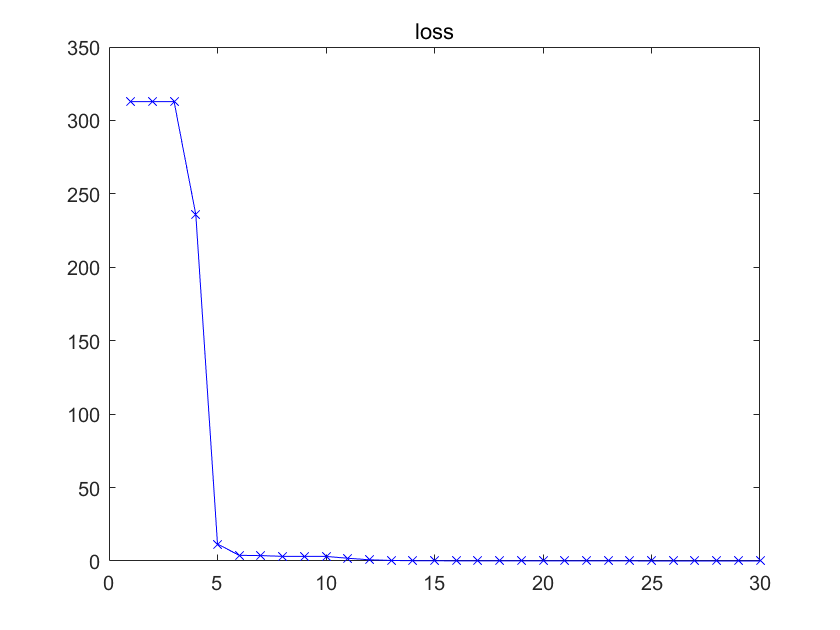

%When lemda = 10^-5, lemda_k = 1
w1 = Levbg_Maqdt_alg(x,y);%multipule run algorithm

%error = 0.000015

**When lemda = 10^-3, there is no significant impact of training loss.**

final loss=0.024129
error=0.000048

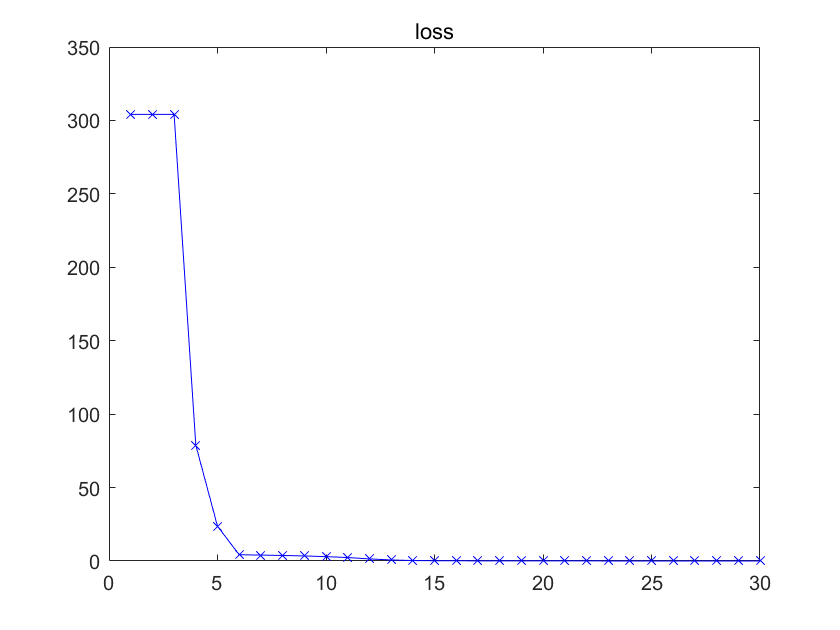

%When lemda = 10^-3,lemda_k = 1
w2 = Levbg_Maqdt_alg(x,y);

%error = 0.000048

**When lemda = 1, the final training loss is larger than before since the training loss put more weight on norm(w) instead of norm(r).**

final loss=7.373758
error=0.014748

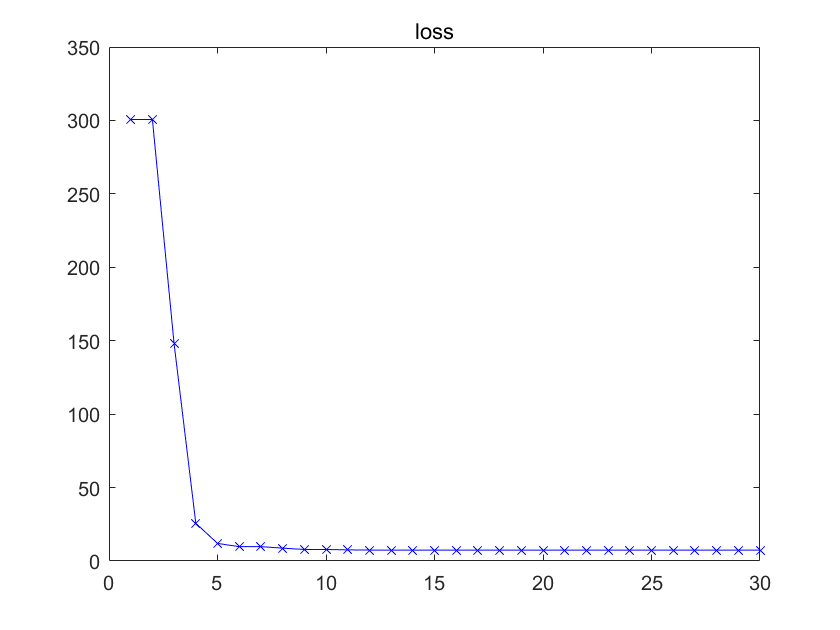

%When lemda = 1,lemda_k = 1
w3 = Levbg_Maqdt_alg(x,y);

%error = 0.014748

Try different initializations for the Levenberg-Marquardt algorithm and see the effect on final model training loss error. **Now lemda = 10^-5 not changing. Let w equals to 0.1. My stopping criteria for single run algorithm is loss smaller than 1 or 50 loops if loss not smaller than 1.**

final loss=0.998053

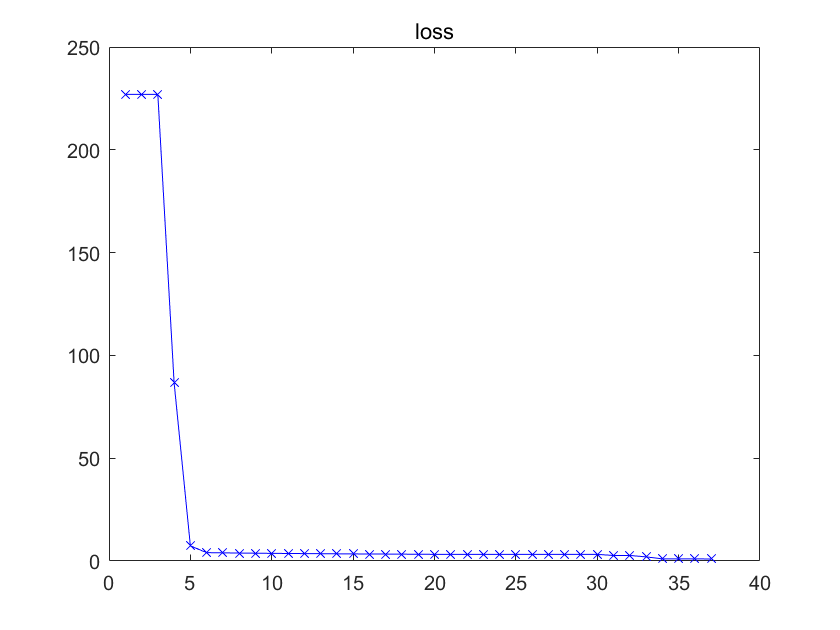

error=0.001996

%When lemda = 10^-5,w = 0.1
w4 = LevbgMaqdt_alg(x,y);%single run algorithm

**When lemda = 10^-5 and initial w much larger than 1. We the loss needs more iterations to drop since initial w is far from optimized w. Also the loss is larger when than w = 0.1**

final loss=1.271375

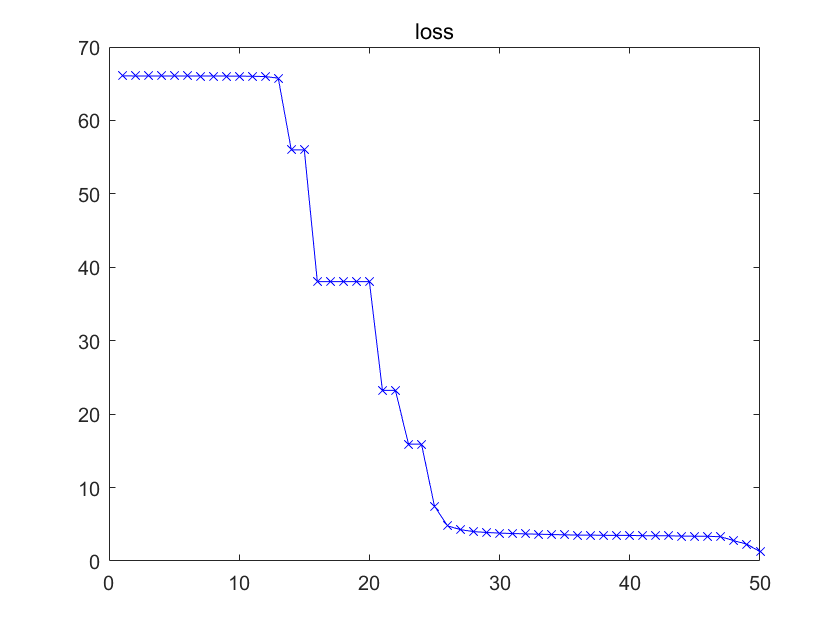

error=0.002543

%When lemda = 10^-5,w = 3
w5 = LevbgMaqdt_alg(x,y);%single run algorithm

ii. Test the model on another set of NT randomly generated points ˜x (n) , n = 1, 2, ¨ ¨ ¨ NT (which are different from those used to train the network). Show how you compute the error for test points (try different values of NT between 50 and 300) and report the values. Summarize your training and testing error metrics for different initializations, different choices of λ and NT. Comment on your results.

**Generate 50 data points as test set.**

%generate 50 data points as test set
[x,y] = rand_gen(50);

**Use multiple run LM algorithm to calculate the error.**

%When lemda = 10^-5
w6 = Levbg_Maqdt_alg(x,y);

final loss=0.000842
error=0.000017

%error = 0.000017

%When lemda = 10^-3
w7 = Levbg_Maqdt_alg(x,y);

final loss=0.013910
error=0.000278

%error = 0.000278

%When lemda = 1
w8 = Levbg_Maqdt_alg(x,y);

final loss=2.848993
error=0.056980

%error = 0.05698

**Generate 100 data points as test set.**

%generate 100 data points as test set
[x,y] = rand_gen(100);

**Use multiple run LM algorithm to calculate the error.**

%When lemda = 10^-5
w15 = Levbg_Maqdt_alg(x,y);

final loss=0.001735
error=0.000017

%error = 0.000017

%When lemda = 10^-3
w16 = Levbg_Maqdt_alg(x,y);

final loss=0.015339
error=0.000153

%error = 0.000153

%When lemda = 1
w17 = Levbg_Maqdt_alg(x,y);

final loss=3.519118
error=0.035191

%error = 0.035191

**Generate 200 data points as test set.**

[x,y] = rand_gen(200);

%When lemda = 10^-5
w9 = Levbg_Maqdt_alg(x,y);

final loss=0.001886
error=0.000009

%error = 0.000009

%When lemda = 10^-3
w10 = Levbg_Maqdt_alg(x,y);

final loss=0.018087
error=0.000090

%error = 0.00009

%When lemda = 1
w11 = Levbg_Maqdt_alg(x,y);

final loss=4.214546
error=0.021073

%error = 0.021073

**Generate 300 data points as test set.**

[x,y] = rand_gen(300);

%When lemda = 10^-5
w12 = Levbg_Maqdt_alg(x,y);

final loss=0.003997
error=0.000013

%error = 0.0000013

%When lemda = 10^-3
w13 = Levbg_Maqdt_alg(x,y);

final loss=0.020934
error=0.000070

%error = 0.00007

%When lemda = 1
w14 = Levbg_Maqdt_alg(x,y);

final loss=5.205768
error=0.017353

%error = 0.017353

%first row is NT
%first column is lembda
%others are the test error matrix of corresponding NT and lembda
err_matx = [0 50 100 200 300;
        10^-5 0.0017 0.0017 0.0009 0.00013;
        10^-3 0.0278 0.0153 0.009 0.007;
        1 5.698 3.5191 2.1073 1.7353]

err_matx =          0   50.0000  100.0000  200.0000  300.0000
    0.0000    0.0017    0.0017    0.0009    0.0001
    0.0010    0.0278    0.0153    0.0090    0.0070
    1.0000    5.6980    3.5191    2.1073    1.7353


%To see the trend easier, I multiple all the error rate with 100


**The error matrix shows that as test NT approaches training NT(500), the error rates decrease. Also, as lembda grows, the error rates also increase.**